# Oefenzitting 0: Basis gebruik MATLAB

## 1. De MATLAB-omgeving

Wanneer je MATLAB opstart, zie je een venster opgedeeld in drie kolommen:

- Current Folder: de map waarin je werkt

- Command Window: hierin kun je enkele commando's ingeven voor een onmiddellijke uitvoer. Dit is niet bedoeld om volledige programma's in te schrijven.

- Workspace: een overzicht van alle variabelen die momenteel zijn gemaakt, en de waarden die ze hebben.

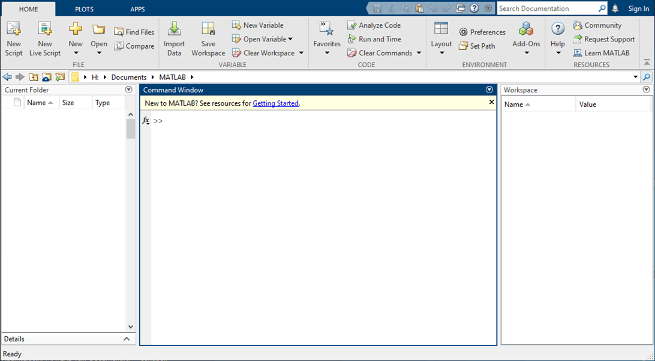

Op dit moment lees je een live-script. De editor hiervoor is nog een vierde vak in je venster.

Er zijn drie manieren om in MATLAB commando's in te geven. Deze zijn allemaal vergelijkbaar met een tegenhanger in Python:

- Het Command Window: dit is zoals de REPL in Python. Als je ooit Python hebt opgestart zonder een Python-programma in te laden, zou je hiermee vertrouwd moeten zijn.

- Een MATLAB-script: dit bevat de code voor de MATLAB-programma's die je zou schrijven. Een script is een bestand met extensie *.m. De tegenhanger in Python is een bestand met extensie *.py. 

- Een live-script: dit is een interactief document met zowel code als geformatteerde tekst. Een live-script is een bestand met extensie *.mlx. Dit is zoals een Jupyter-notebook ( *.ipynb).

### 1.1 Het Command Window

Dit venster gebruik je om snel een commando te testen. Hierin schrijf je geen volledige programma's.

**Oefening****: **Bereken in het Command Window $3 + 6$, $3 \times 6$, en $3^6$.

**Oefening****: **Onderzoek hoe je een natuurlijk logaritme kan berekenen:

- Het commando `lookfor` can gebruikt worden om functies op te zoeken die te maken hebben met een bepaald onderwerp. Voer bijvoorbeeld "`lookfor logarithm" `in. Dit geeft een lijst met potentieel relevante functies, met daarnaast een korte beschrijving van wat ze doen.

- Zoek het meest relevante commando in de lijst (waarschijnlijk bovenaan) en raadpleeg de documentatie met het commando` help NAAM `waarbij je in `NAAM` de naam van de functie invult. 

- Bereken $\exp(\ln 2)$. Verifieer dat je het verwachte resultaat krijgt.

Met het commando `format` kun je bepalen hoe een getal wordt weergegeven. Nadien worden alle getallen in een vaste notatie getoond.

**Oefening:** Voer in het Command Window "`format long"` in. Bereken daarna $\sqrt{\frac{1}{2}}$. Herhaal nadien deze oefening met

- `format long e`

- `format short e`

- `format short`

**Oefening****: **Definieer een variabele `x` met de waarde 1. Is deze nu geregistreerd in het Workspace-venster?

### 1.2 Scripts

### 1.2.1 Maken en uitvoeren van scripts

Het merendeel van de tijd zul je in de script-editor werken. Hierin schrijf je je MATLAB-programma's. 

Lees in de navigatiebalk welke map momenteel geopend is:

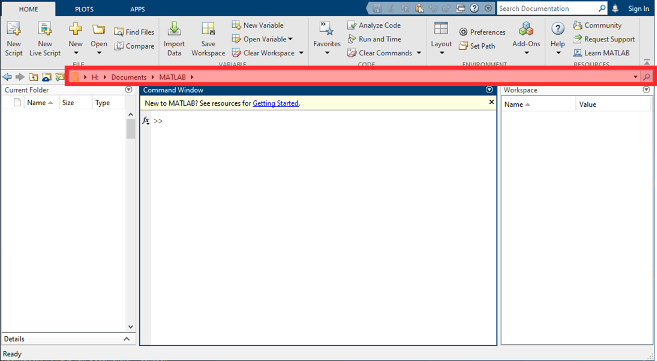

**Oefening****: **Schrijf nu een eenvoudig "Hello World"-programma als volgt:

- Maak een nieuw script (let op: geen live-script!) en sla het op onder de bestandsnaam `hello.m` in deze map. 

- Schrijf in het bestand de lijn `disp('Hello world')`

- Klik op de Run-knop bovenaan op je scherm onder het tabblad `Editor`. Zie je de uitvoer van het programma in je Command Window? 

Opmerking: in de bestandsnaam zet je beter geen speciale tekens, zoals spaties of leestekens. Dit komt omdat de bestandsnaam automatisch ook een MATLAB-commando wordt, en die kunnen geen speciale tekens bevatten.

**Oefening:** Maak nu een ander script `hello2.m` aan met dezelfde inhoud, maar dit keer in een andere map. Als je het script probeert uit te voeren, zal MATLAB waarschuwen dat het script zich niet in het "pad" bevindt. Het pad is een lijst bestanden waar MATLAB naar kijkt als je code uitvoert. Elk bestand dat je wil uitvoeren moet in het pad zitten. Op een Windows-systeem bestaat het pad initieel uit de map My `Documents\MATLAB`. De waarschuwingsboodschap die je gekregen hebt, geeft twee opties:

- Change Folder: verplaats het pad naar de map waar `hello2.m` zit. Dan zit je eerder gemaakte bestand `hello.m `niet meer in het pad en zal je dat niet meer kunnen uitvoeren.

- Add to Path: breid het huidige pad uit met het nieuwe bestand. We kiezen voor deze optie.

Kun je nu `hello2.m` uitvoeren?

### 1.2.2. Interactie met de MATLAB-omgeving

**Oefening****: **Schrijf in het bestand `hello.m` de lijn `disp(x)`. Dit drukt de waarde van `x` af. Verwacht je dat `x` in dit programma al gedefinieerd is? 

In de vorige sectie had je `x=1` gedefinieerd in het Command Window. Deze waarde werd nu gebruikt door het script. Hieruit leren we dat een script ook variabelen kan gebruiken die elders toegekend zijn. Je zal merken dat dit onoverzichtelijk kan worden als je niet meer onthoudt welke variabelen gedefinieerd waren en welke waarden die hadden. Om die reden is het ***sterk aangeraden*** om in het begin van elk script het commando `clear all` te plaatsen. Dit wist alle vooraf gedefinieerde variabelen. De enige variabelen die het script dan kan gebruiken, zijn de variabelen die in het script zelf gedefinieerd zijn. Zo is er geen verwarring mogelijk. 

**Oefening****: **Wis de inhoud van het programma `hello.m`. Schrijf in `hello.m` nu het volgende:

`clear all`

`disp(x)`

Geeft dit nu een foutmelding als je het bestand uitvoert? Is dat wat je verwacht?

Als je in een script een berekening uitvoert, wordt het resultaat van die berekening in het Command Window afgedrukt, tenzij je de lijn eindigt met een `";"`. Om je uitvoer overzichtelijk te houden, zal je de meeste lijnen code zo eindigen. 

**Oefening****: **schrijf in `hello.m` het volgende:

`clear all`

`a = 1`

`b = 2;`

Let op de puntkomma aan het einde van de tweede lijn! Voer het programma uit. Welke variabelen worden afgedrukt in het Command Window?

### 1.3 Live-scripts

Deze handleiding is zelf een live-script. Zo een script is opgedeeld in secties met blokken code in. Die secties zijn gescheiden door horizontale lijnen. Je kan ze uitvoeren met de knop "`Run Section`" bovenaan het MATLAB-venster, onder het tabblad "`Live Editor`". Die is vaak nuttiger dan de "`Run`"-knop, die het hele document uitvoert. 

**Oefening:** Voer deze sectie uit. Verifieer dat het resultaat van de onderstaande code naast het document wordt getoond.

% Berekening van pi met de formule van Euler:
% 1/1 + 1/4 + 1/9 + 1/16 + ... = pi^2 / 6, uitgerekend tot 1000 termen
n = 1:1000;
pi_euler = sqrt(sum(6 ./ n.^2))

pi_euler = 3.1406

Voer in het vervolg ook elk blok code uit nadat je het gelezen hebt.

Elk blok code kan de variabelen gebruiken uit een eerder blok code. Het volgende geeft dus geen foutmelding als je het uitvoert:

pi_euler

pi_euler = 3.1406

Alle blokken code die in dezelfde sectie staan, worden samen uitgevoerd. In het eerste blok definiëren we

k = 0:2;

De variabele k gebruiken we in het volgende blok:

% Formule van Ramanujan
pi_inv = 2*sqrt(2) / 9801 * sum(factorial(4*k) .* (1103 + 26390*k) ./ factorial(k).^4 ./ 396 .^ (4*k));
pi_ramanujan = 1 / pi_inv

pi_ramanujan = 3.1416

De bovenstaande twee blokken worden allebei uitgevoerd als je op "`Run Section`" klikt.

## 2. Rekenen met matrices en vectoren

clear all

MATLAB is gebaseerd op rekenen met matrices. In de appendix bij de cursustekst vind je enkele manieren om matrices te definiëren.

**Oefening****:** Definieer in onderstaand blok code de matrix 


$$A = \pmatrix{1 & 2 \cr 3 & 4}$$


A = [ 1 2 
      3 4 ]

A =      1     2
     3     4


Tussen haakjes: lijnen die beginnen met een "`%`"-symbool zijn commentaar.

**Oefening: **Bereken hieronder $\det(A + I_2)$ met 1 lijn code. (Hint: behalve de cursustekst kun je ook gebruik maken van `lookfor, help, en doc`, zoals eerder aangegeven)

det(A + eye(2))

ans = 4.0000

Het $(i,j)$-de element van $A$ benoem je in MATLAB als `A(i,j)`. Merk op dat 

- dit dezelfde syntax is als het oproepen van een functie. 

- de indices beginnen van 1 en niet vanaf 0. 

Als je toch een index 0 opgeeft, krijg je een foutmelding. Hier lokken we die opzettelijk uit als illustratie:

A(1,0)

Index in position 2 is invalid. Array indices must be positive integers or logical values.

**Oefening****: **Geef met 1 commando de eerste rij van $A$, en geef eveneens in 1 lijn de eerste kolom van $A$. Bekijk hiervoor de appendix bij de cursustekst.

A(1, :)

ans =      1     2


A(:, 1)

ans =      1
     3


Vectoren zijn matrices met 1 rij of met 1 kolom. **Er bestaat dus geen apart gegevenstype voor vectoren. **Het is aan de gebruiker om te bepalen of vectoren best als rij- of kolommatrices gegeven worden. Als vectoren inconsequent in rijvorm of kolomvorm bepaald zijn, kan onverwacht gedrag optreden. Bijvoorbeeld, we schrijven


$$v = \pmatrix{1 & 2} \in \mathbb{R}^{1 \times 2}
\quad\text{en}\quad w = \pmatrix{3 \cr 4} \in \mathbb{R}^{2 \times 1}$$


als volgt:

v = [1 2]

v =      1     2


w = [3; 4]

w =      3
     4


Als we het inwendig product berekenen met `dot`, zal MATLAB de som $1 \times 3 + 2 \times 4$ berekenen:

dot(v, w)

ans = 11

Als we echter $v + w$ berekenen, krijgen we het volgende (onverwachte) resultaat:

v + w

ans =      4     5
     5     6


Hieruit trekken we de les dat het belangrijk is om van elke vector te weten of deze in rij- of kolomformaat gespecificeerd is. Sommige functies kunnen zich anders gedragen naargelang de notatie van de vector.

Het wisselen tussen rij- en kolomformaat is transponeren, zoals gekend uit de lineaire algebra. De operator hiervoor is het enkele aanhalingsteken`' `(voor $v \in \mathbb{C}^{n}$ berekent deze operator ook het complex toegevoegde). Een alternatief is `transpose` of `reshape`. Bekijk hiervoor de documentatie met `help` of `doc`.   

v'

ans =      1
     2


## 3. Controlestructuren

clear all

De gebruikelijke controlestructuren zoals `if`-testen en `for`-lussen vind je ook terug in MATLAB. Lees de documentatie van `if, die we als volgt opvragen`

help if

--- help for MATLAB keyword if ---

 if - Execute statements if condition is true
    This MATLAB function evaluates an expression, and executes a group of
    statements when the expression is true.

    Syntax
      if expression, statements, end

    Examples
      Use if, elseif, and else for Conditional Assignment
      Compare Arrays
      Test Arrays for Equality
      Compare Character Vectors
      Test Values for Inequality
      Evaluate Multiple Conditions i

Een meer uitgebreide uitleg kun je opvragen met `doc if`.

Let op: elke `if`-uitdrukking eindig je met `end`. De indentatie van de lijnen heeft geen invloed op het gedrag van het programma, in tegenstelling tot `if`-structuren in Python.

De volgende lijn code vraagt aan de gebruiker een getal $x$. De gebruiker zal $x$ ingeven in het Command Window.

x = input('Geef hier de waarde van x in: ')

x = 5

**Oefening:** Bereken in onderstaand blok code de absolute waarde van $x$ met behulp van de `if`-structuur.

% bereken hieronder y = x als x >= 0 en y = -x als x < 0.
if x >= 0
    y = x
elseif x < 0
    y=-x
end

y = 5

Een andere controlestructuur is de `for`-lus. Voer het onderstaande uit om de documentatie van `for` te tonen.

help for

--- help for MATLAB keyword for ---

 for - for loop to repeat specified number of times
    This MATLAB function executes a group of statements in a loop for a
    specified number of times.

    Syntax
      for index = values, statements, end

    Examples
      Assign Matrix Values
      Decrement Values
      Execute Statements for Specified Values
      Repeat Statements for Each Matrix Column

    See also end, break, continue, parfor, <a hr

% Alternatief voor meer uitleg: doc for

**Oefening:** Bereken $n! = 1 \times 2 \times \cdots  \times n$ met een for-lus. Voor de eenvoud kiezen we een vaste waarde voor $n$. 

n = 7

n = 7

Logisch gezien moet de berekining er ongeveer als volgt uitzien:

| y = 1 

| herhaal voor i = 1 tot en met n: y = y * i.

Implementeer dit nu hieronder in MATLAB:

y = 1

y = 1

for i=1:+1:n
    y = y*i;
end
display(y)

y = 5040

Wordt de waarde van $y$ in elke iteratie op het scherm getoond? Zo ja, herinner je je nog hoe je dit kan vermijden?

While-lussen bestaan ook, maar die zullen we hier niet gebruiken.

## 4. Vectorisatie

clear all

Vectorisatie is het uitvoeren van een eenvoudige bewerking op meerdere getallen tegelijk. Dit principe, dat we dadelijk in detail bekijken, is in MATLAB vaak de voorkeursmethode om een herhaalde bewerking uit te voeren. Doorgaans kun je hetzelfde bereiken met een for-lus, maar vectorisatie is vaak eenvoudiger en efficiënter. Als je al met NumPy gewerkt hebt, heb je hier misschien al een voorsmaakje van gekregen. 

Veronderstel dat we enkele meetpunten $(x_i)_{i=1}^N$ hebben. Bijvoorbeeld 10 gelijk gespreide punten in het interval $[0, 2\pi]$. Deze kunnen ingeven met het commando

x = linspace(0, 2*pi, 10)

x =          0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832


Als we de rij $(y_i)_{i=1}^N$ met $y_i = \sin x_i$ willen berekenen, zouden we dat kunnen doen met de volgende for-lus:

y = zeros(size(x)); % initieel een rij nullen, even groot als x
for i = 1:length(x)
    y(i) = sin(x(i));
end
y

y =          0    0.6428    0.9848    0.8660    0.3420   -0.3420   -0.8660   -0.9848   -0.6428   -0.0000


De gevectoriseerde oplossing is echter compacter en efficiënter. De MATLAB-functie `sin` (en bovendien veel andere functies: `tan`, `log`, `sqrt`, `exp`, `abs`, ...) kun ook toepassen op vectoren en matrices. Voor een vector $x = [x_1, \dots, x_n]$ is `sin(x)` gedefinieerd als $[\sin x_1, \dots, \sin x_n]$. Dit geeft de volgende code:

y = sin(x)

y =          0    0.6428    0.9848    0.8660    0.3420   -0.3420   -0.8660   -0.9848   -0.6428   -0.0000


Voor sommige functies moet je opletten omdat ze verward kunnen worden met matrixvermenigvuldiging. Bijvoorbeeld: we hebben twee vectoren $u = [u_1,\dots,u_n]$ en $v = [v_1, \dots, v_n]$. We willen het product $w := [u_1v_1, \dots, u_n v_n]$ kennen. Aangezien $v$ en $w$ beide $n \times 1$-matrices zijn, zou het symbool "`*"` voor de vermenigvuldiging geinterpreteerd kunnen worden als een matrixvermenigvuldiging zoals in de lineaire algebra, terwijl we hier geinteresseerd zijn in elementsgewijse vermenigvuldiging. Daarvoor hebben we de operator "`.*"`. 

Bijvoorbeeld:

u = [1 2 3 4]

u =      1     2     3     4


v = [2 4 6 8]

v =      2     4     6     8



w = u .* v

w =      2     8    18    32


Als we gewoon het symbool "`*`" hadden gebruikt voor de vermenigvuldiging, zouden we een foutmelding krijgen dat de formaten van $u$ en $w$ niet compatibel zijn om een matrixvermenigvuldiging uit te voeren. Hier lokken we die foutmelding opzettelijk uit als illustratie:

u * v

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Related documentation

Andere operatoren die verward zouden kunnen worden met matrixvermenigvuldiging zijn "`/`" en "`\"` voor de deling en "`^"` voor de machtsverheffing. Gebruik "`./", ".\", of ".^" `als je gevectoriseerde bewerkingen bedoelt`.`

Nog een voorbeeld: herinner je hoe we hierboven de formule van Euler hebben uitgerekend: $\frac{\pi^2}{6} = \sum_{n=1}^\infty \frac{1}{n^2}$, oftewel $\pi = \sqrt{\sum_{n=1}^\infty \frac{6}{n^2}}$. We berekenen de som tot maximaal $N$ termen.

N = 1000

N = 1000

Als we dit met een for-lus hadden gedaan, hadden we deze code:

som = 0;
for n = 1:N
    som = som + 6 / n^2;
end
pi_euler = sqrt(som)

pi_euler = 3.1406

De gevectoriseerde oplossing is iets eenvoudiger. Met behulp van het commando `sum` dat alle elementen van een vector optelt, krijgen we

n = 1:N % dit maakt een rijvector [1 2 ... N].

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


pi_euler = sqrt(sum(6 ./ n.^2))

pi_euler = 3.1406

We ontleden de code als volgt: `n` is de rijvector $[1\quad 2\quad 3\quad \cdots \quad N]$. Met de formule `6 ./ n.^2` krijgen we de vector $\left[\frac{6}{1^2} \quad \frac{6}{2^2} \quad \frac{6}{3^2} \quad\cdots\quad \frac{6}{N^2}\right]$. Als we de som van alle elementen van deze vector nemen, krijgen we $\sum_{n=1}^N \frac{6}{n^2}$. Nadien hebben we hiervan enkel nog de vierkantswortel nodig.

Nu zou je moeten begrijpen wat de bovenstaande symbolen betekenen en waarom we "`./`" en "`.^`" gebruiken.

**Oefening:** Voor $k \in \mathbb{N}$ geldt dat $\ln(k!) = \ln(1 \times 2 \times \dots \times k) = \ln(1) + \ln(2) + \dots + \ln (k)$. Gebruik deze formule om $\ln(k!)$ te berekenen voor $k = 10$. Gebruik vectorisatie. 

n = 1:10

n =      1     2     3     4     5     6     7     8     9    10


ln_k_fac = sum(log(n))

ln_k_fac = 15.1044


% check
ln_k_fac = log(factorial(10))

ln_k_fac = 15.1044

Het kan even duren om vectorisatie in de vingers te krijgen, maar eens je de techniek beheerst, krijg je veel eenvoudigere code en bespaar je werk.

## 5. Grafieken tekenen

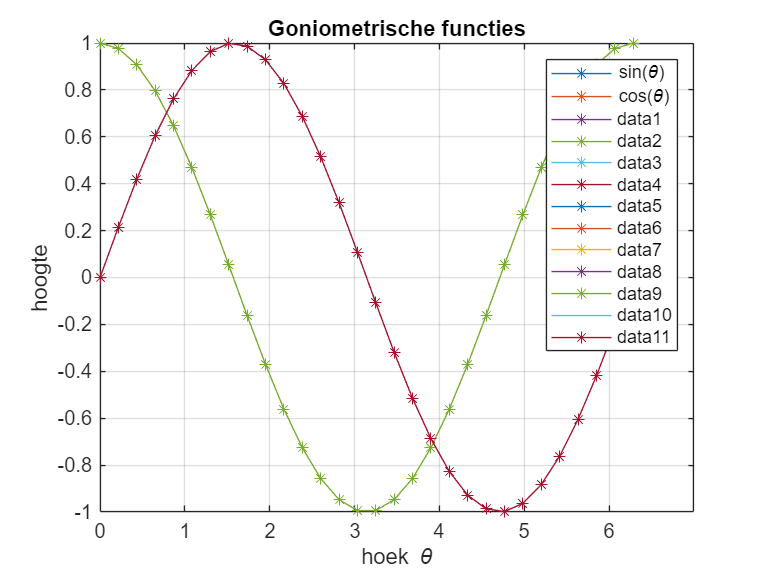

clear all

De MATLAB-commando's om grafieken te tekenen hebben gediend als model voor vele andere softwarepaketten. De Python-module Matplotlib is bijvoorbeeld ontworpen om compatibel te zijn met MATLAB. Als je daarmee al vertrouwd bent, heb je hier niet veel nieuws te leren. De equivalente commando's hebben vaak dezelfde naam en dezelfde gebruikswijze.

In de praktijk tekenen we nooit echt de grafiek van een functie. We evalueren die functie in een voldoende groot aantal punten $\{x_i\}$ en verbinden de puntenkoppels $\{(x_i, y_i)\}$ met een lijn. 

**Oefening:** Definieer 30 gelijk gespreide punten $x_i$ in $[0, 2\pi]$ (voor een geheugensteuntje kun je terugkijken naar de sectie over vectorisatie). Maak een vector $y$ met componenten $y_i = \sin x_i$. 

x = linspace(0, 2*pi, 30)

x =          0    0.2167    0.4333    0.6500    0.8666    1.0833    1.3000    1.5166    1.7333    1.9500    2.1666    2.3833    2.5999    2.8166    3.0333    3.2499    3.4666    3.6832    3.8999    4.1166    4.3332    4.5499    4.7666    4.9832    5.1999    5.4165    5.6332    5.8499    6.0665    6.2832


y = sin(x)

y =          0    0.2150    0.4199    0.6052    0.7622    0.8835    0.9635    0.9985    0.9868    0.9290    0.8277    0.6877    0.5156    0.3193    0.1081   -0.1081   -0.3193   -0.5156   -0.6877   -0.8277   -0.9290   -0.9868   -0.9985   -0.9635   -0.8835   -0.7622   -0.6052   -0.4199   -0.2150   -0.0000


Een grafiek van $y$ als functie van $x$ kun je maken als volgt:

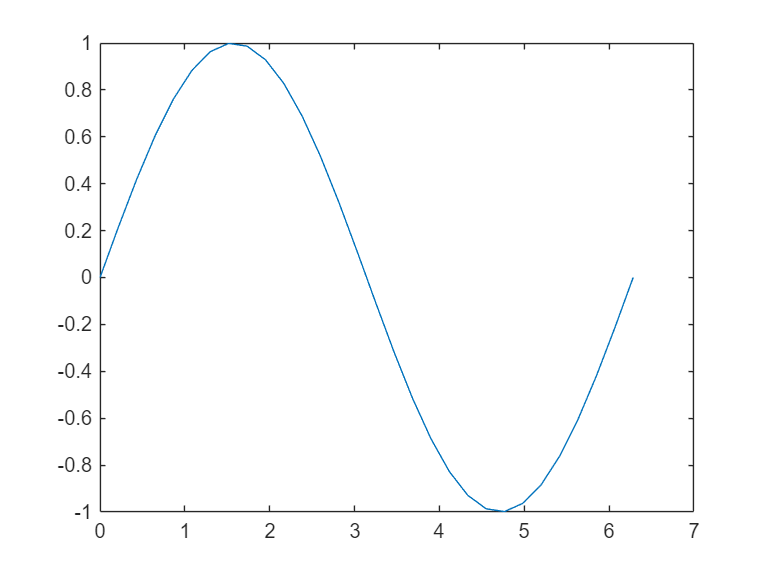

plot(x,y)

Meestal is het nuttig om de datapunten te markeren in een grafiek. Dit doe je als volgt.

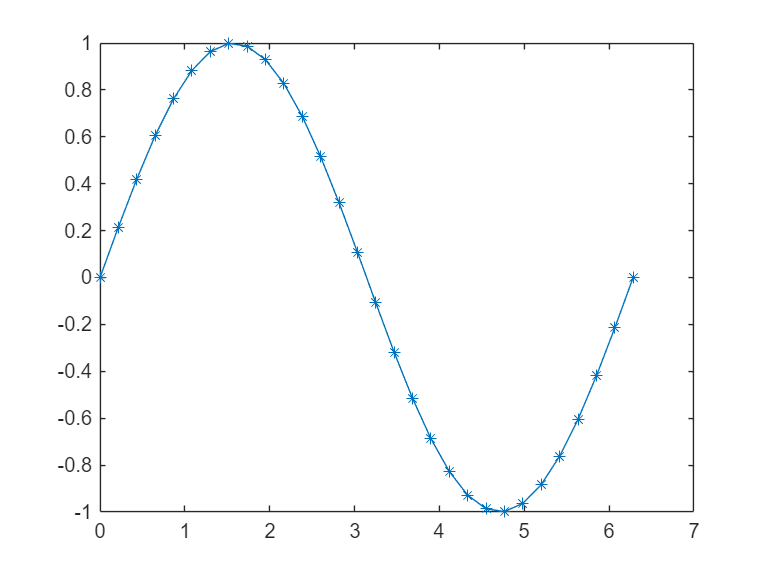

plot(x, y, '-*')-0.7385   -0.8807   -0.9664   -0.9906   -0.9522

Nadien voeg je informatie toe: labels, titels, enz. Deze kun je achteraf specificeren en moeten dus niet allemaal aan het `plot`-commando worden meegegeven. Het onderstaande voegt informatie toe aan de meest recente grafiek die aangemaakt is.

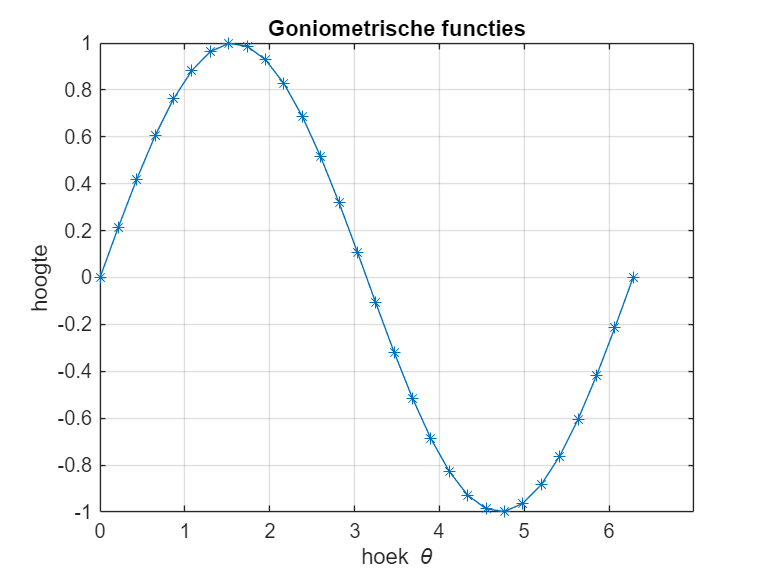

xlabel('hoek \theta')
ylabel('hoogte')
title('Goniometrische functies')
xticks([0, 1, 2, 3, 4, 5, 6])
grid on

Als je bovenop een grafiek nog een tweede lijn wil plotten, moet je eerst `hold on` ingeven. Dan zullen alle volgende grafieken op dezelfde figuur worden getekend, totdat het commando `hold off` wordt uitgevoerd.

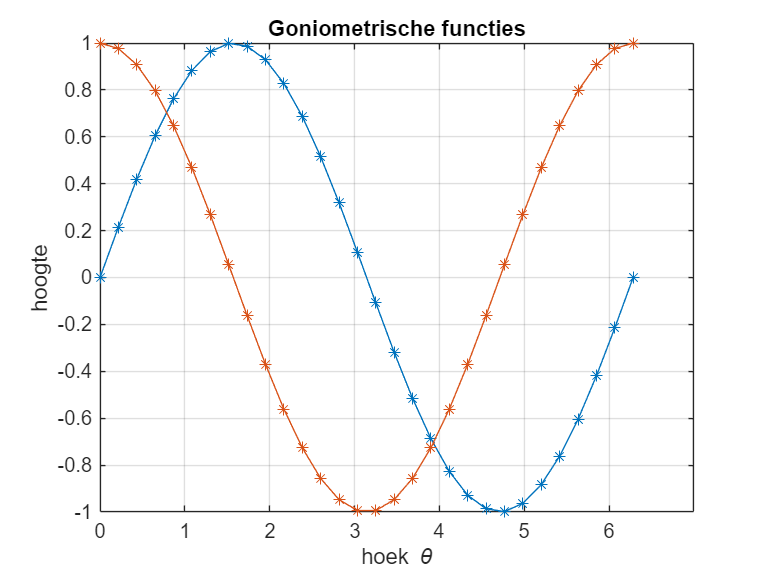

hold on
plot(x, cos(x), '-*')

We voegen een legende toe met de labels in de volgorde waarin we de grafieken getekend hebben:

legend('sin(\theta)', 'cos(\theta)')

Vergeet niet om `hold off` te gebruiken om te vermijden dat de volgende grafieken bovenop deze figuur getekend worden.

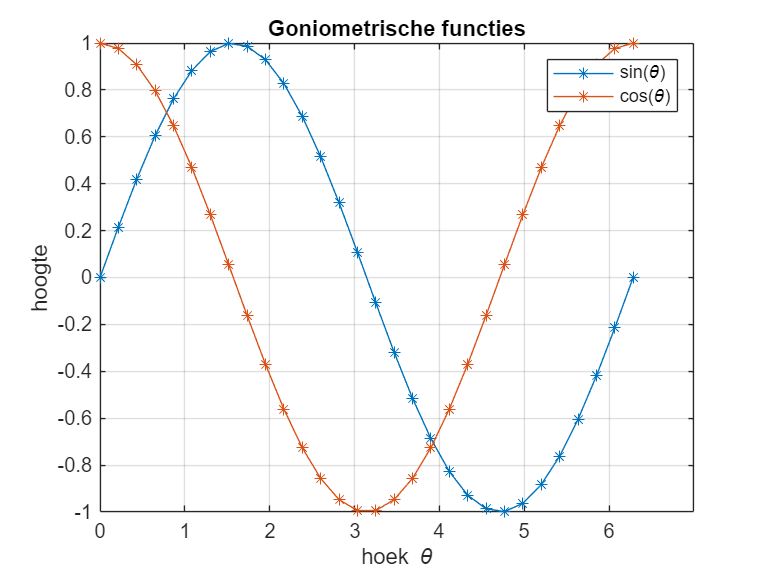

hold off

In de plaats van een lineair geschaalde grafiek kun je ook een figuur met logaritmisch geschaalde assen maken. De ingebouwde commando's zijn `semilogx`, `semilogy`, en `loglog`. Zoek met de commando's `help semilogx` enzovoorts uit wat deze doen. Het gebruik ervan is identiek hetzelfde als bij `plot.` Met de ingebouwde commando's voor log-plots is de ijking van de assen leesbaarder.

**Oefening:** Maak een grafiek van $\exp(-x)$ voor $x$ gaande van $-10$ tot $10$. Zorg dat de verticale as logaritmisch geschaald is en de horizontale as niet. Benoem de assen en markeer de abcissen $[-10,\quad -5,\quad 0,\quad 5,\quad 10]$ op de $x$-as.

x = linspace(-10, 10, 100)

x =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


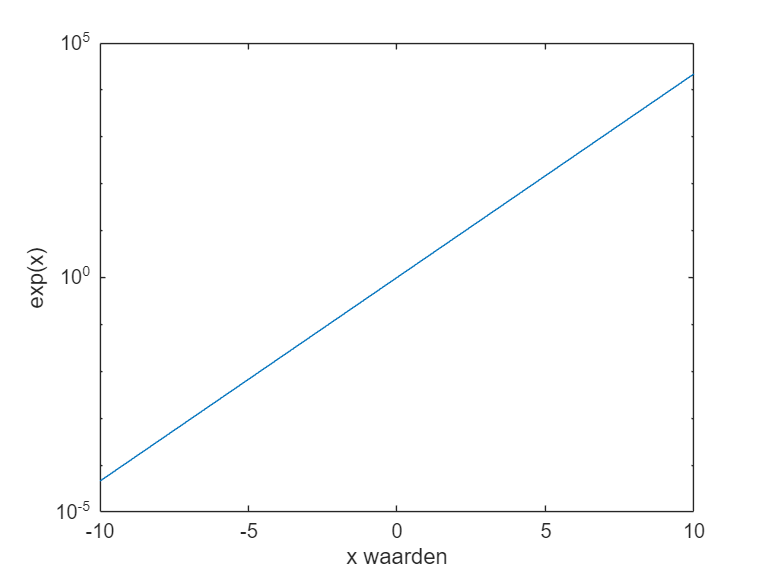

xticks([-10, -5, 0, 5, 10])

y = exp(x)

y = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001


semilogy(x,y)
xlabel('x waarden')
ylabel('exp(x)')